# Word-of-mouth estimation

Numerical examples for word-of-mouth estimation in a directed tree. The unknown $\mathbf{x} = [x_1, x_2]^\top \in \mathbb{R}^2$, with mean $\hat{\mathbf{x}}_0$ and covariance $\mathbf{P}_0 = \mathrm{diag}(2, 1)$, collects the amplitudes of a cosine and a sine wave of frequency $\omega$, revealed at every $t \in \mathbb{N}$ through the scalar signal (1)


$$s_t(\mathbf{x}) = \mathbf{c}_t^\top \mathbf{x} = x_1 \cos(\omega t) + \rho\, x_2 \sin(\omega t), \qquad \mathbf{c}_t = [\cos(\omega t), \rho \sin(\omega t)]^\top,$$


where $\rho > 0$ is the gain of the sine channel. The eigenvalues of $\mathbf{P}_0$ differ from the start, and with $\rho = 2$ the signal informs more about $x_2$ than about $x_1$, so the eigenvalues of $\mathbf{P}_t$ stay apart: their ratio grows from 2 to about 4.

Sec. 3 only requires $\mathbf{c}_t \neq \mathbf{0}$, so single entries may vanish at some $t$. Writing $\mathbf{c}_t = \mathbf{D}[\cos(\omega t), \sin(\omega t)]^\top$, with $\mathbf{D} = \mathrm{diag}(1, \rho)$, every window of $\bar{t} + 1$ steps gives, for every $t$,


$$\underline{c} = \min(1, \rho^2)\, \frac{\bar{t} + 1 - |\sin((\bar{t} + 1)\omega) / \sin \omega|}{2}, \qquad \bar{c} = \max(1, \rho^2)\, \frac{\bar{t} + 1 + |\sin((\bar{t} + 1)\omega) / \sin \omega|}{2},$$


so $\{\mathbf{c}_t\}$ is strongly persistently exciting (Assumption 1) for every $\omega \notin \pi\mathbb{Z}$. For $\omega \in \pi\mathbb{Z}$, $\sin(\omega t) = 0$ for every $t$, and $x_2$ is never observed. `fcn_param` takes the smallest window with $|\sin((\bar{t} + 1)\omega) / \sin \omega| \le (\bar{t} + 1)/2$, i.e. over which every direction gets at least half of its average information: $\bar{t} = 2$ for $\omega = 1$.

clc
clear
close all

## Setup

Fix the following:

- `rng(0)`: random seed, so that every `randn` call is reproducible;

- `fcn_param`: frequency $\omega$ and gain $\rho$ of the regressor, prior $(\hat{\mathbf{x}}_0, \mathbf{P}_0)$, horizon $T$, noise variance $\varepsilon^{ij}$, normalizations $\eta$ and the two trees;

- `fcn_plot_param`: plotting style, one color per run. All figures open in their own figure windows, not in the live script.

rng(0);

% initialize problem parameters
param = fcn_param();
fprintf("Assumption 1: c_lo = %.4g, c_hi = %.4g over windows of t_bar + 1 = %d steps; ||c_t||^2 <= %.4g, c_t' P0 c_t <= %.4g\n", ...
    param.c_lo, param.c_hi, param.t_bar + 1, param.c_sup, param.q_max);

Assumption 1: c_lo = 1.416, c_hi = 6.335 over windows of t_bar + 1 = 3 steps; ||c_t||^2 <= 4, c_t' P0 c_t <= 4



% initialize plotting style: colors of the "gem" palette, 1 blue (eta = 0), 2 red (eta = 1), ..., 5 green (tree A)
plot_param = fcn_plot_param(5);

## Networks

The agents $\mathcal{V} = \{1, \dots, r\}$ form a directed tree rooted at $r$, with every edge $(j, i) \in \mathcal{E}$ pointing from a child $j$ to its parent $i$. The fictitious agent $0$, the signal $s_t(\mathbf{x})$, is a child of every leaf $i \in \mathcal{L}$, and every edge $(j, i)$ of the augmented graph carries an observation noise of variance $\varepsilon^{ij}$. The rate of convergence is governed by the shortest distance from each agent to a leaf,


$$\delta_i = \left\{\begin{array}{ll} 0, & i \in \mathcal{L}, \\ 1 + \min_{j \in \bar{\mathcal{C}}^i} \delta_j, & \mathrm{otherwise}. \end{array}\right.$$


- **Tree A**, $\delta_r = 1$: leaf 1 is a child of the root 6, leaves 2 and 3 sit three relays below it.

- **Tree B**, $\delta_r = 2$: tree A with a new leaf attached to leaf 1, so that the closest leaf sits two relays below the root. The new leaf takes label 1 and the labels of tree A shift by one, so that the root keeps the largest label, $r = 7$.

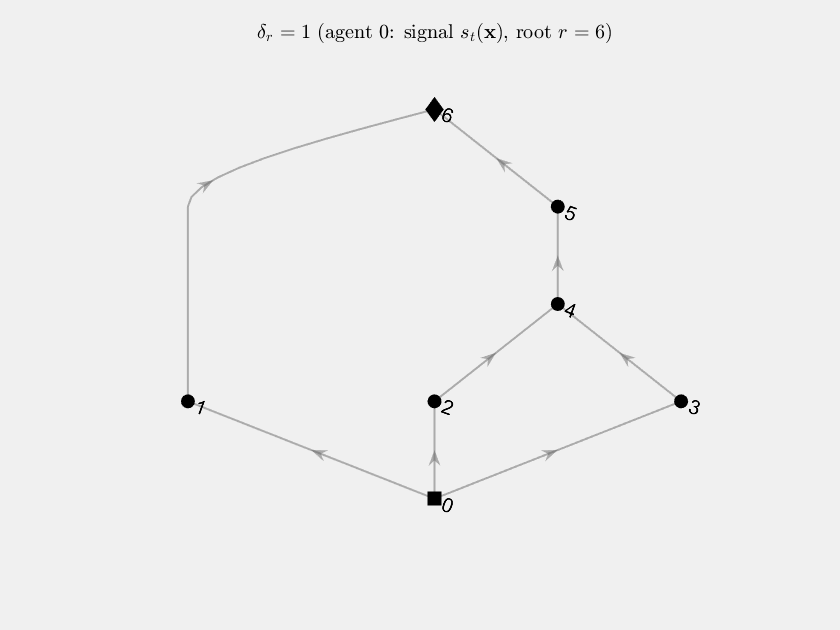

% directed trees, augmented with the edges (0, i) from the signal to every leaf
net_A = fcn_tree(param.E_A, param.epsilon);         % delta_r = 1
net_B = fcn_tree(param.E_B, param.epsilon);         % delta_r = 2

% draw both trees (Fig. 1)
fcn_plot_tree(net_A, plot_param);

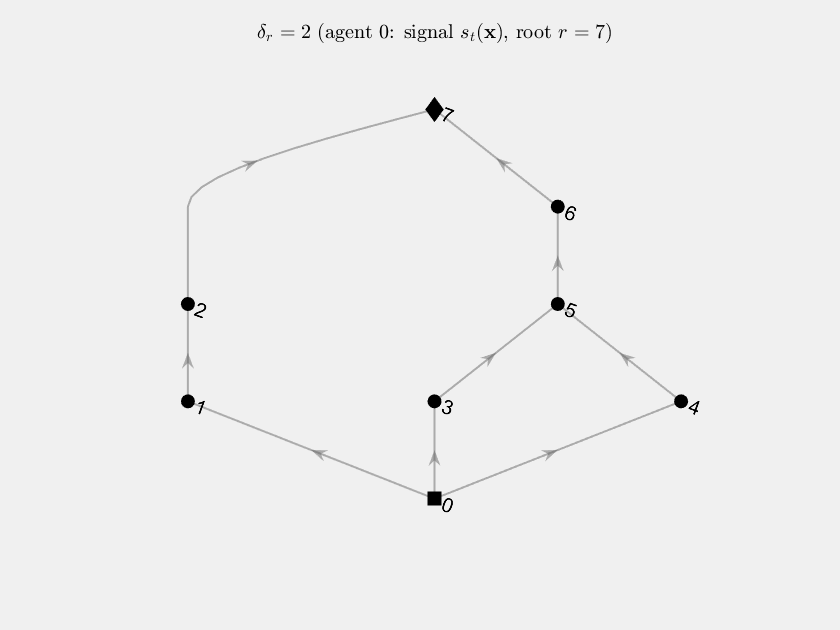

fcn_plot_tree(net_B, plot_param);

## Word-of-mouth estimation

At time $t$, every agent starts from the common pair $(\hat{\mathbf{x}}_{t-1}, \mathbf{P}_{t-1})$ broadcast by the root. From the leaves to the root, agent $i$ merges its observations $y_t^{ij}$, $j \in \bar{\mathcal{C}}^i$, by inverse-variance weighting (4), performs one RLS step (6a)-(6b), and transmits its signal estimate to its parent:


$$\begin{array}{c} y_t^i = (\varphi_t^i)^{\eta} \sum_{j \in \bar{\mathcal{C}}^i} \frac{y_t^{ij} - b_t^{ij}}{a_t^{ij}\,\varphi_t^{ij}}, \\ \hat{\mathbf{x}}_t^i = \hat{\mathbf{x}}_{t-1} + \frac{\mathbf{P}_{t-1}\mathbf{c}_t}{q_t + \varphi_t^i}\left(\frac{y_t^i}{a_t^i} - s_t(\hat{\mathbf{x}}_{t-1})\right), \\ \mathbf{P}_t^i = \mathbf{P}_{t-1} - \frac{\mathbf{P}_{t-1}\mathbf{c}_t\mathbf{c}_t^\top \mathbf{P}_{t-1}}{q_t + \varphi_t^i}, \\ s_t^i(\hat{\mathbf{x}}_t^i) = a_t^i\, \mathbf{c}_t^\top \hat{\mathbf{x}}_t^i, \end{array}$$


with $q_t = \mathbf{c}_t^\top \mathbf{P}_{t-1}\mathbf{c}_t$ and with the parameters $a_t^{ij}$, $b_t^{ij}$, $\varphi_t^{ij}$, $\varphi_t^i$ and $a_t^i = (\varphi_t^i)^{\eta - 1}$ of Proposition 1. The root closes the round with $(\hat{\mathbf{x}}_t, \mathbf{P}_t) := (\hat{\mathbf{x}}_t^r, \mathbf{P}_t^r)$. See `fcn_run`, `fcn_agent` and `fcn_phi`.

## Convergence rate

By Lemma 1 and Theorem 1, with


$$\alpha_i = \frac{2\,(4-2\eta)^{\delta_i} - 2}{3 - 2\eta}, \qquad \beta = \frac{1}{1 + \alpha_r} = \frac{3 - 2\eta}{2\,(4-2\eta)^{\delta_r} + 1 - 2\eta},$$


there exist constants $\underline{\pi}, \bar{\pi} > 0$ such that


$$\underline{\pi}\,(t+1)^{-\beta}\,\mathbf{I} \preceq \mathbf{P}_{t-1} \preceq \bar{\pi}\,(t+1)^{-\beta}\,\mathbf{I}, \qquad t \in \mathbb{N}.$$


`fcn_constants` computes these constants explicitly, before the simulation and for every $t$, from the constants $L_r\, q_t^{-\alpha_r} \le \varphi_t^r \le U_r\, q_t^{-\alpha_r}$ of Lemma 1. Every run gets one figure, opened in its own figure window so that it can be edited, on log-log axes, with $\lambda_{\max}(\mathbf{P}_{t-1})$ and $\lambda_{\min}(\mathbf{P}_{t-1})$ against the upper bound $\bar{\pi}\,(t+1)^{-\beta}$, a straight line of slope $-\beta$ for $t \gg 1$, with the region below the bound filled. The lower bound is not drawn: since $\bar{\pi}$ enters $\underline{\pi}$ raised to $\alpha_r$, it lies many decades below the eigenvalues (its value is printed).

The eigenvalues reach the slope $-\beta$ only slowly, as $\varphi_t^{ij}$ carries the factor $(1 + q_t/\varphi_t^j)^2$ (Proposition 1), which tends to one only as fast as $q_t$ vanishes, i.e. like $t^{-\beta}$.

## Experiment 1: normalization

Tree B ($\delta_r = 2$) is run for every $\eta$ in `param.eta_norm`. By Theorem 1, $\beta = 1/11$ for $\eta = 0$ and $\beta = 1/7$ for $\eta = 1$, so $\eta = 1$ learns faster. Tree A would show no difference: for $\delta_r = 1$, $\alpha_r = 2$ and $\beta = 1/3$ for every $\eta$, so the normalization only matters from two relays on. The figures share the same y-range, from the highest upper bound down to the lowest value reached by a smallest eigenvalue, so they can be compared directly.

n_eta = numel(param.eta_norm);
const_norm = cell(n_eta, 1);
traj_norm = cell(n_eta, 1);
ev_norm = cell(n_eta, 1);

for k = 1:n_eta
    eta = param.eta_norm(k);
    const_norm{k} = fcn_constants(param, net_B, eta);               % explicit constants of Lemma 1 and Theorem 1 (offline)
    traj_norm{k} = fcn_traj(param, net_B);                          % draw x and the noise sequences
    traj_norm{k} = fcn_run(traj_norm{k}, param, net_B, eta);        % word-of-mouth estimation up to time T
    ev_norm{k} = fcn_eig(traj_norm{k}, const_norm{k});              % eigenvalues of P_{t-1}
    fcn_print_rate("B", net_B, eta, const_norm{k}, ev_norm{k});
end

tree B, delta_r = 2, eta = 0: alpha_r = 10, beta = 0.09091
  Theorem 1: [pi_lo, pi_hi] = [2.15e-42, 9.82]
  Lemma 1, root: [L_r, U_r] = [8.27e-25, 2.12e+07], phi_t^r q_t^alpha_r in [23.7, 4.63e+06] over the run, limit 1
  checks over the run: Lemma 1 holds for every agent: true, Theorem 1 holds at every t: true
tree B, delta_r = 2, eta = 1: alpha_r = 6, beta = 0.1429
  Theorem 1: [pi_lo, pi_hi] = [1.78e-17, 8.81]
  Lemma 1, root: [L_r, U_r] = [9.54e-07, 2.15e+04], phi_t^r q_t^alpha_r in [2.07, 5.1e+03] over the run, limit 1
  checks over the run: Lemma 1 holds for every agent: true, Theorem 1 holds at every t: true


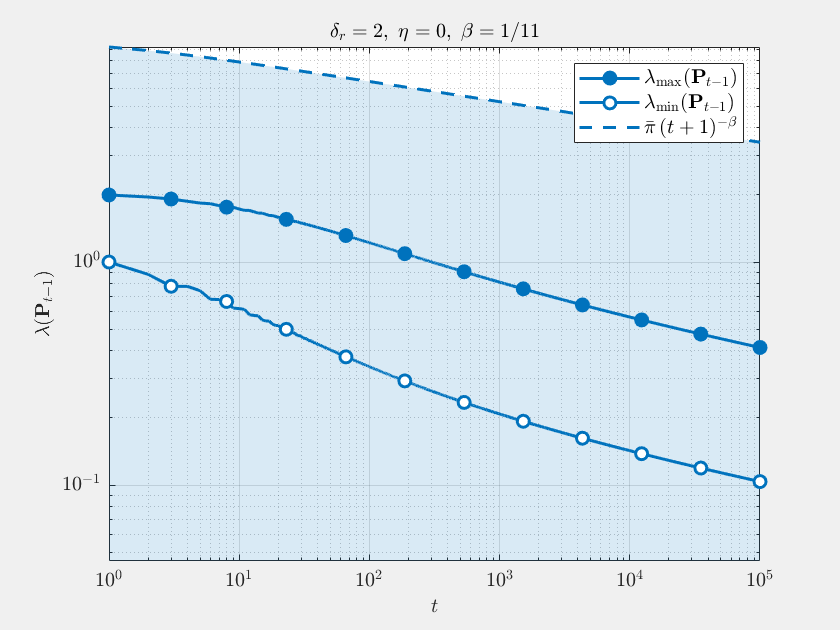

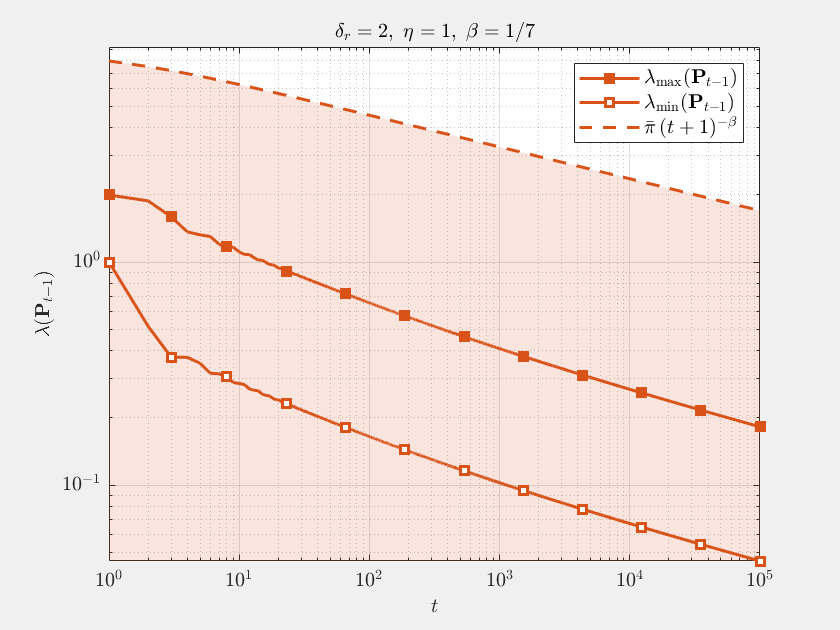


% common y-range: from the highest upper bound down to the lowest smallest eigenvalue
y_lim = fcn_ylim(ev_norm, const_norm);
for k = 1:n_eta
    fcn_plot_rate(ev_norm{k}, const_norm{k}, net_B, param.eta_norm(k), plot_param, k, y_lim);
end

## Experiment 2: depth

Trees B ($\delta_r = 2$) and A ($\delta_r = 1$) are run with the same normalization, $\eta$ = `param.eta_depth`. With $\eta = 1$, $\beta = 1/7$ for tree B and $\beta = 1/3$ for tree A: one relay less on the shortest path more than doubles the rate exponent. The run of tree B is the one of experiment 1 with the same $\eta$, when available, and is drawn in the same color (red); tree A is drawn in green. The figures share the same y-range, from the highest upper bound down to the lowest value reached by a smallest eigenvalue, so they can be compared directly.

nets = {net_B; net_A};
names = ["B"; "A"];
n_net = numel(nets);
const_depth = cell(n_net, 1);
traj_depth = cell(n_net, 1);
ev_depth = cell(n_net, 1);
eta = param.eta_depth;

% run of experiment 1 with the same tree and eta, if any: reused, and drawn in the same color
k_norm = find(param.eta_norm == eta, 1);
if isempty(k_norm)
    k_plot = [3; 5];                                                % tree B yellow, tree A green
else
    k_plot = [k_norm; 5];                                           % tree B as in experiment 1 (red for eta = 1), tree A green
end

for d = 1:n_net
    net = nets{d};
    const_depth{d} = fcn_constants(param, net, eta);                % explicit constants of Lemma 1 and Theorem 1 (offline)
    if isequal(net, net_B) && ~isempty(k_norm) && exist("traj_norm", "var")
        traj_depth{d} = traj_norm{k_norm};                          % same tree and eta as in experiment 1: reuse that run
    else
        traj_depth{d} = fcn_traj(param, net);                       % draw x and the noise sequences
        traj_depth{d} = fcn_run(traj_depth{d}, param, net, eta);    % word-of-mouth estimation up to time T
    end
    ev_depth{d} = fcn_eig(traj_depth{d}, const_depth{d});           % eigenvalues of P_{t-1}
    fcn_print_rate(names(d), net, eta, const_depth{d}, ev_depth{d});
end

tree B, delta_r = 2, eta = 1: alpha_r = 6, beta = 0.1429
  Theorem 1: [pi_lo, pi_hi] = [1.78e-17, 8.81]
  Lemma 1, root: [L_r, U_r] = [9.54e-07, 2.15e+04], phi_t^r q_t^alpha_r in [2.07, 5.1e+03] over the run, limit 1
  checks over the run: Lemma 1 holds for every agent: true, Theorem 1 holds at every t: true
tree A, delta_r = 1, eta = 1: alpha_r = 2, beta = 0.3333
  Theorem 1: [pi_lo, pi_hi] = [3.64e-13, 7.3]
  Lemma 1, root: [L_r, U_r] = [3.73e-09, 41], phi_t^r q_t^alpha_r in [1.04, 22.7] over the run, limit 1
  checks over the run: Lemma 1 holds for every agent: true, Theorem 1 holds at every t: true


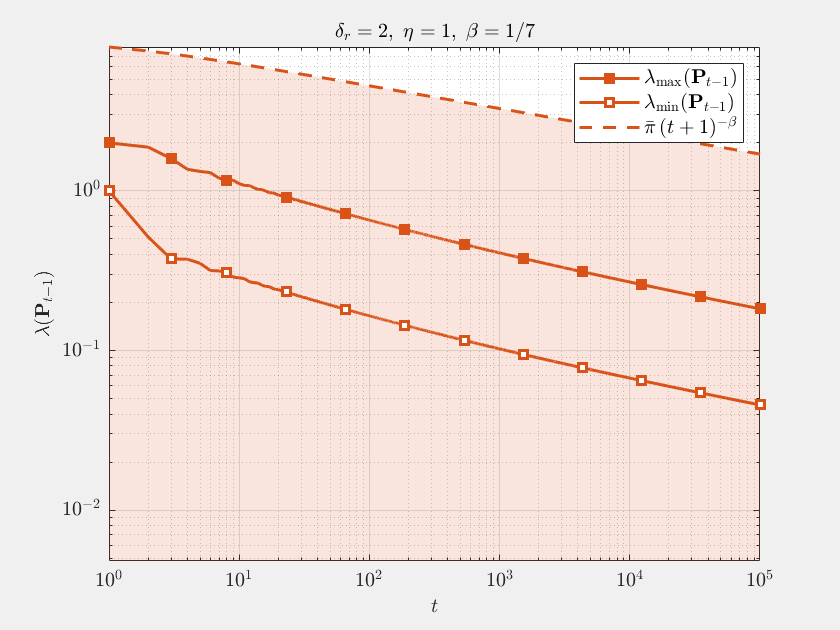

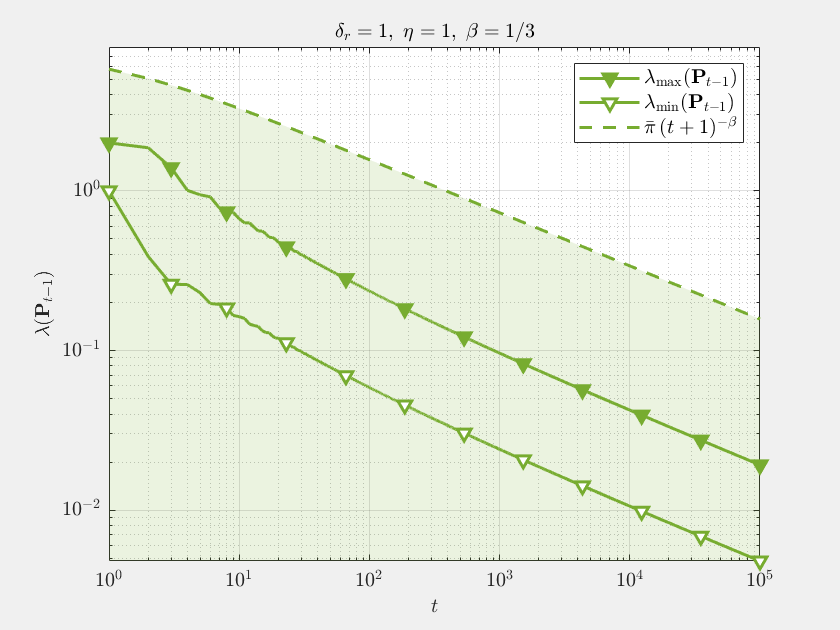


% common y-range: from the highest upper bound down to the lowest smallest eigenvalue
y_lim = fcn_ylim(ev_depth, const_depth);
for d = 1:n_net
    fcn_plot_rate(ev_depth{d}, const_depth{d}, nets{d}, eta, plot_param, k_plot(d), y_lim);
end